# Problem Set 3: Manipulation Estimation and Control

## 1. Dead Reckoning and Kalman Filter

### 1. a. linearized approximation of the system as a function of the current state

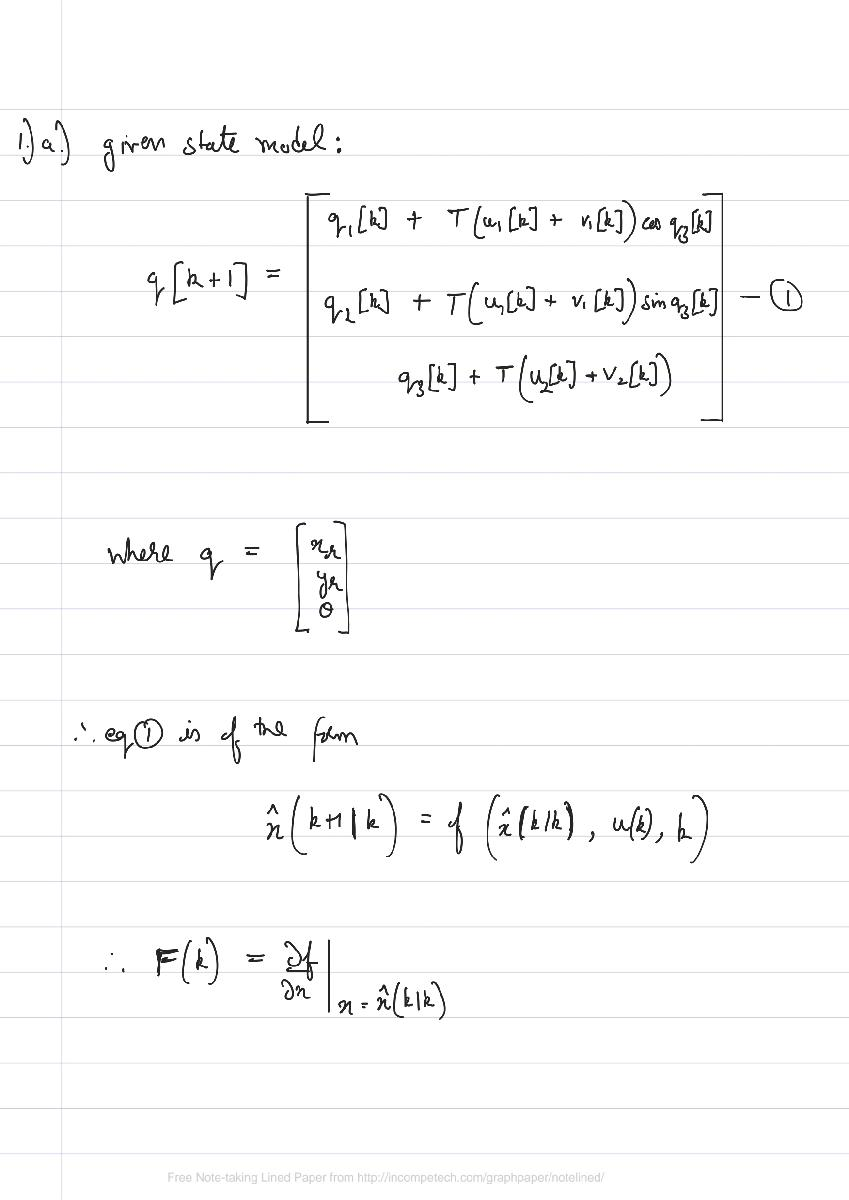

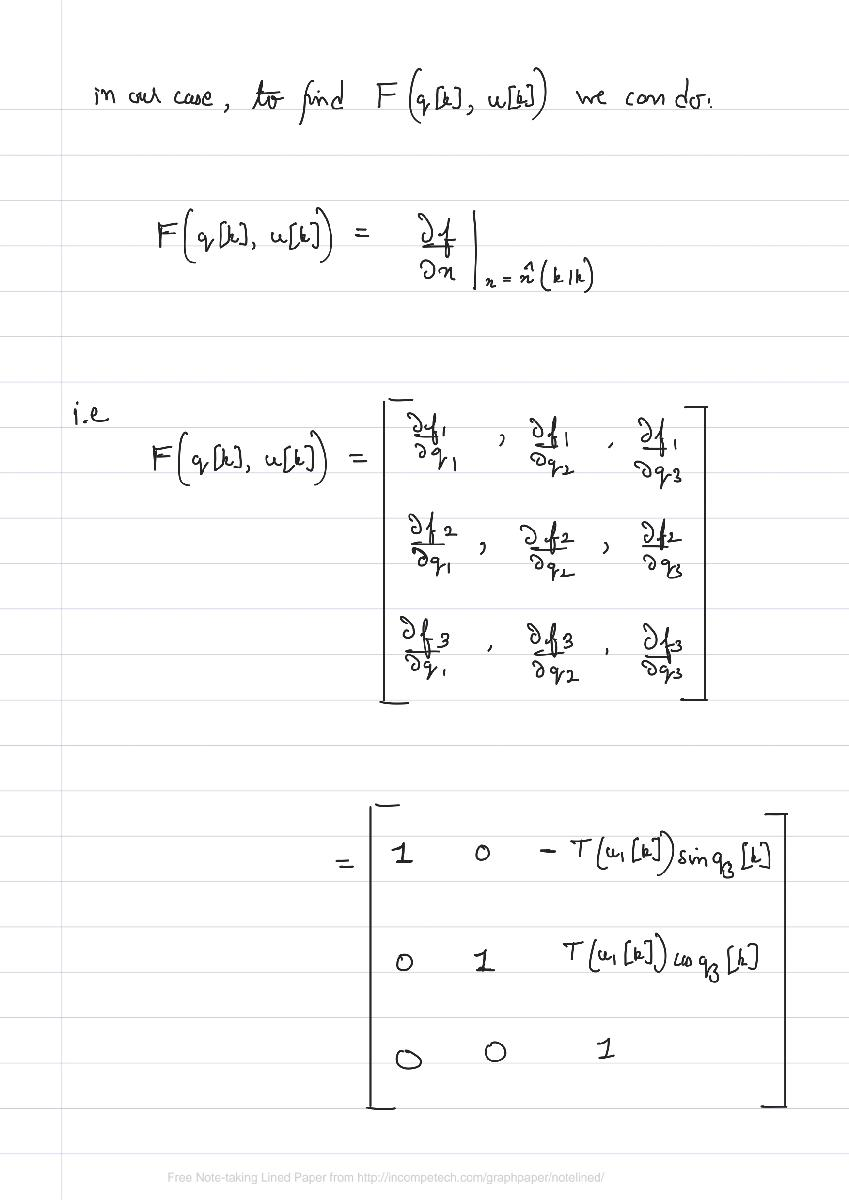

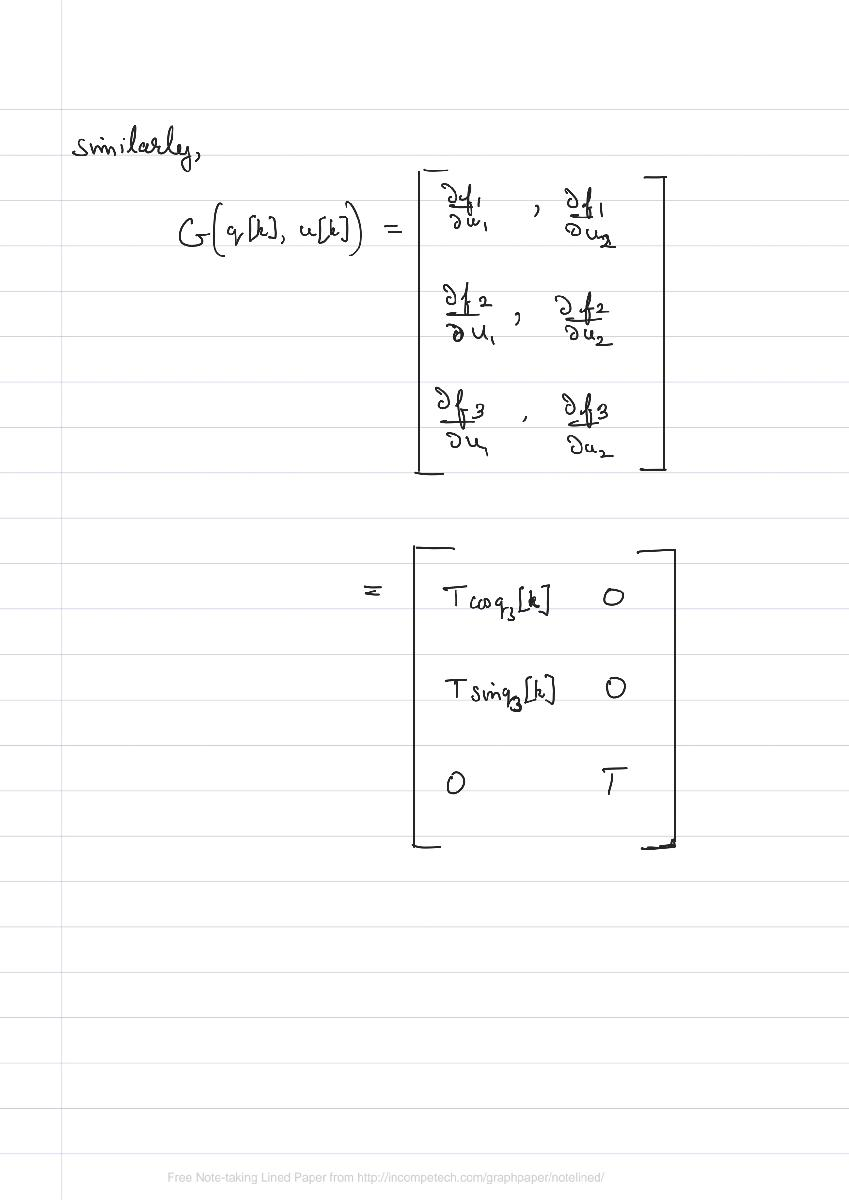

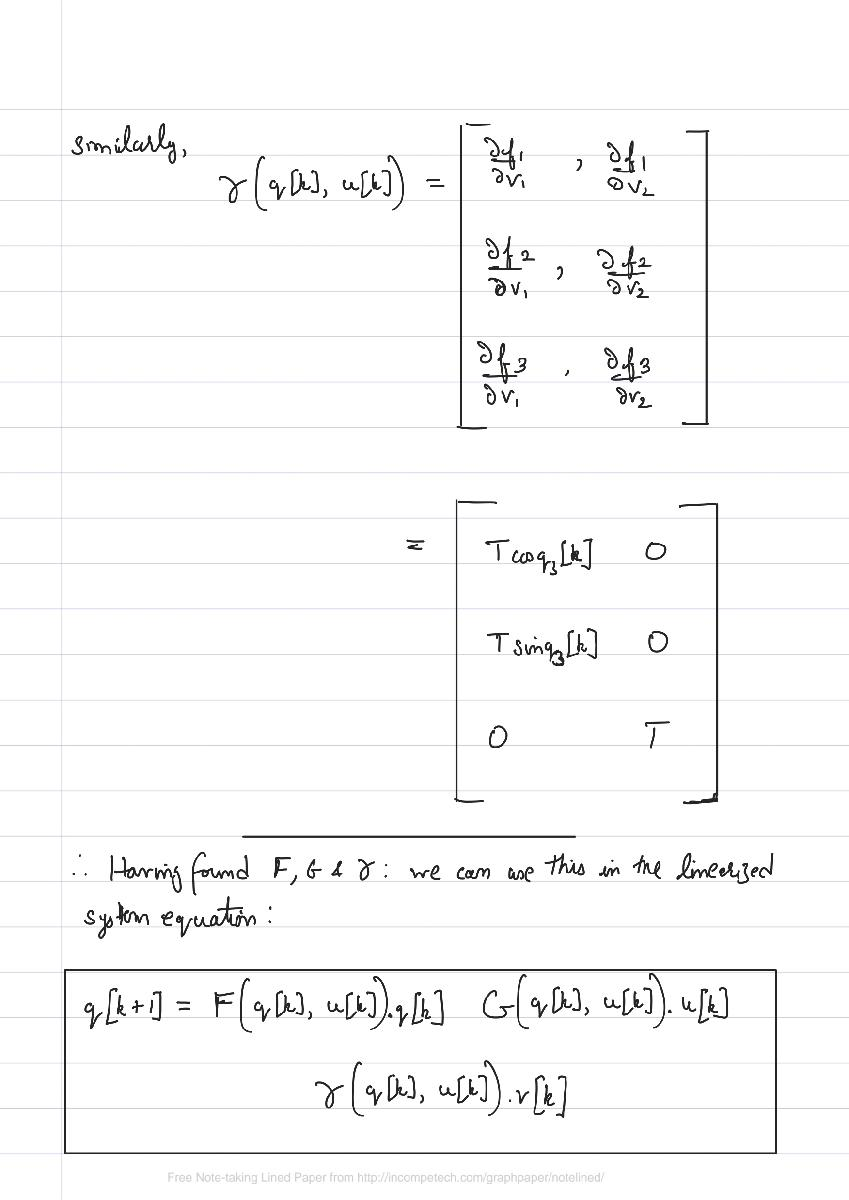

### 1. b. Estimation of Covariance Matrix for process and measurement noise

% import the calibrate.mat file to get:
% Train time params
% - t_groundtruth (absolute time values)
% - q_groundtruth (robot states at the above mentioned time values)
% - u (inputs to robot at time values without any noise)
% 
% Test time values
% - t_y (a vector of times associated with the GPS measurement)
% - y (noisy GPS measurements taken at the times in t y)

load CMU/Assignment_Sem_1/MEC/Assignment_3/'Problem1 (EKF)'/calibration.mat

The error between noisy measurement from actual sensor and groundtruth is recorded. This is then used to calculate the covariance of the measurement noise. 

% get length of time vector
time_duration = size(t_groundTruth,2);

% create a dummy array which will hold the error values
measure_errors = zeros(2,250);

for t = 1:time_duration
    if mod(t,10) == 0
        time = t/10;
        measure_errors(:,time) = (y(:,time) - q_groundTruth(1:2,t));
    end
end

W = cov(measure_errors.')

W =     1.8817    0.0632
    0.0632    2.1384


To calculate the process noise, we use the linearized system model derived in **1.a.**

**<INSERT 1.a. equation>**

% create a dummy array which will hold the error values
process_errors = zeros(2,2500);
timestep = 0.01

timestep = 0.0100


for t = 1:time_duration-1
    % time = t/10;
    
    % calculate the F matrix:
    F = [1 0 -timestep*u(1,t)*sin(q_groundTruth(3,t));
         0 1 timestep*u(1,t)*cos(q_groundTruth(3,t));
         0 0 1];
    
    % calculate the G matrix:
    G = [timestep*cos(q_groundTruth(3,t))  0;
         timestep*sin(q_groundTruth(3,t))   0;
         0                          timestep];

    gamma = G;

    process_errors(:,t) = gamma \ (q_groundTruth(:,t+1) - F*q_groundTruth(:,t) - G*u(:,t));
end

V = cov(process_errors.')

V =     0.2591    0.0010
    0.0010    0.0625
